# Main script

Within this file, everything you need to find and evaluate your magnetic field can be found! Make sure to modify values where it's suggested, and to only run the blocks you need!

## Determine magnetic moment of dipoles

Simulate the magnetic field which arises from a collection of ideal magnetic dipoles, and determine how their magnetization should be set to achieve a target magnetic profile.

### Set general parameters

% Here, specify where all dipoles are located. These position must me
% explicitly specified. Each row corresponds to a dipole, and its columns
% are x, y and z positions.
dipole_positions = [0, 0, -1; 0, 0,  1];

% Now, for each dipole, specify its magnetic moment. Every row should
% relate to the magnetic moment of the dipole of the same row in
% 'dipole_positions'. Set values to 'nan' to indicate that the values
% should be determined by a target field.
dipole_M = [0, 0, nan; 0, 0, nan];

% Here, specify the target magnetic field profile. Any undetermined dipole
% magnetizations will be set to approximate this field, on a 2D-domain
% defined below.
target_field_elementwise = @(x, y, z) [0 0 1];

% Finally, specify on which domain to evaluate the B-field. Currently, only
% discs normal to the z-axis are available
target_domain = struct('origin', [0,0,0], 'R', 1, 'Phi', 0);

### Set computational parameters

These parameters only affect the computational accuracy, not the problem statement

collision_threshold = 0.01;

### Compute stuff

Now, let the magic happen! 

% Check if any dipole is situated exactly in the evaluation area 
dipole_in_domain = false;
% Use line below (but fix it plz) if you're really worried about this
% any(dipole_positions(:, 3) == target_domain.Z)

threshold = collision_threshold * dipole_in_domain;

% Create function from degrees-of-freedom to magnetization:
n = sum(isnan(dipole_M), 'all');
get_M = @(x) insert_params(x, dipole_M);

% Create function handle which returns a vector-type field computator from
% params x
B_func_from_x = @(x) B_function(@(X, Y, Z) get_field(X, Y, Z, dipole_positions, get_M(x), threshold));

% Create a reference field computator handle
B_0 = B_function(@(X, Y, Z) cell2mat(arrayfun(@(x, y, z) reshape(target_field_elementwise(x, y, z), [1 1 3]), X, Y, Z, 'UniformOutput', false)));

% Create an inner product evaluator, with information about evaluation
% domain.
inprod = inner_product(target_domain.R, target_domain.origin, target_domain.Phi);

% GO!!!
[x, B_best] = granny_smith(B_func_from_x, B_0, inprod, n);
x

x = 	1.0e+06 *

    4.8143    4.8143


### Plotting the result

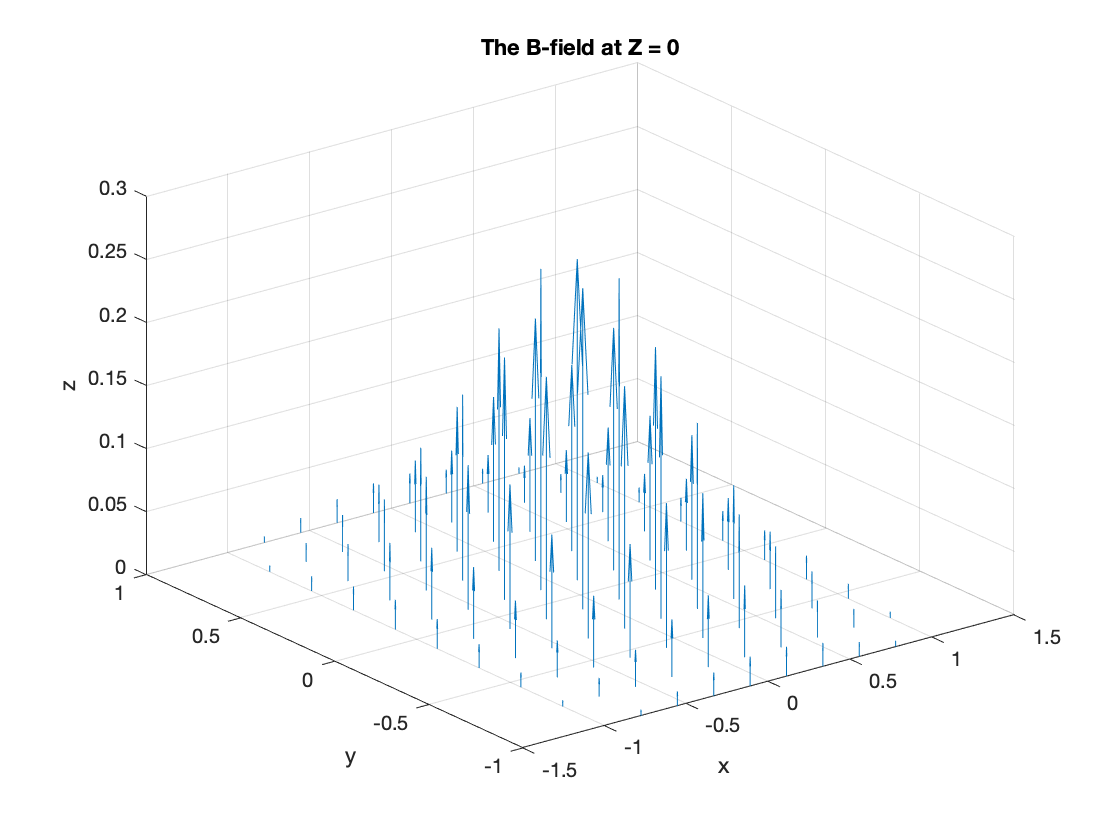

% Select the amount of discretization points
N = 10;

% Select the boundaries of the domain
Xmax = 1;
Ymax = 1;
Z_value = 0;

% Create the mesh
[X,Y,Z] = meshgrid(linspace(-Xmax,Xmax,N),...
    linspace(-Ymax,Ymax,N),Z_value);

% Assigns the B-field and shows the quiver plot
B = B_best(X,Y,Z);

quiver3(X,Y,Z,B(:,:,1),B(:,:,2),B(:,:,3))
hold on
xlabel('x')
ylabel('y')
zlabel('z')
title("The B-field at Z = " + Z_value)
hold off